# Hobbing - Entwicklung der Mathematik

## Definition

### Parametrierung der Transformationsmatrizen

#### TM der Maschine

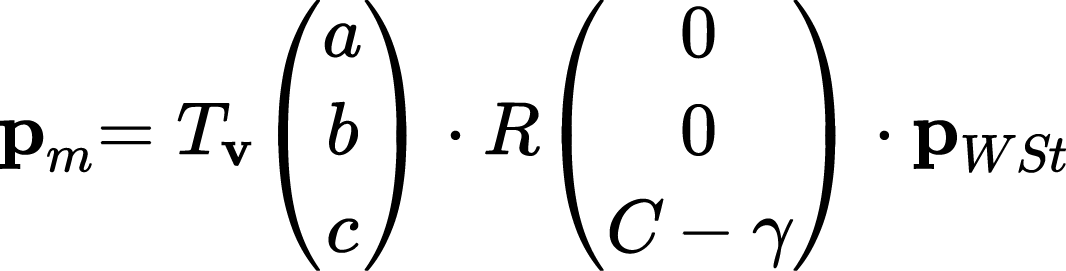

Versatz Achsen zu Null C

syms a b c

Winkel C

syms C

Gamma:

- Offset auf die Werkstück-Rotation, falls Werkstück verdreht aufgespannt is

- Zahn-Zahnlücke Korrektur

syms ga

#### TM Werkzeugkoordinatensystem

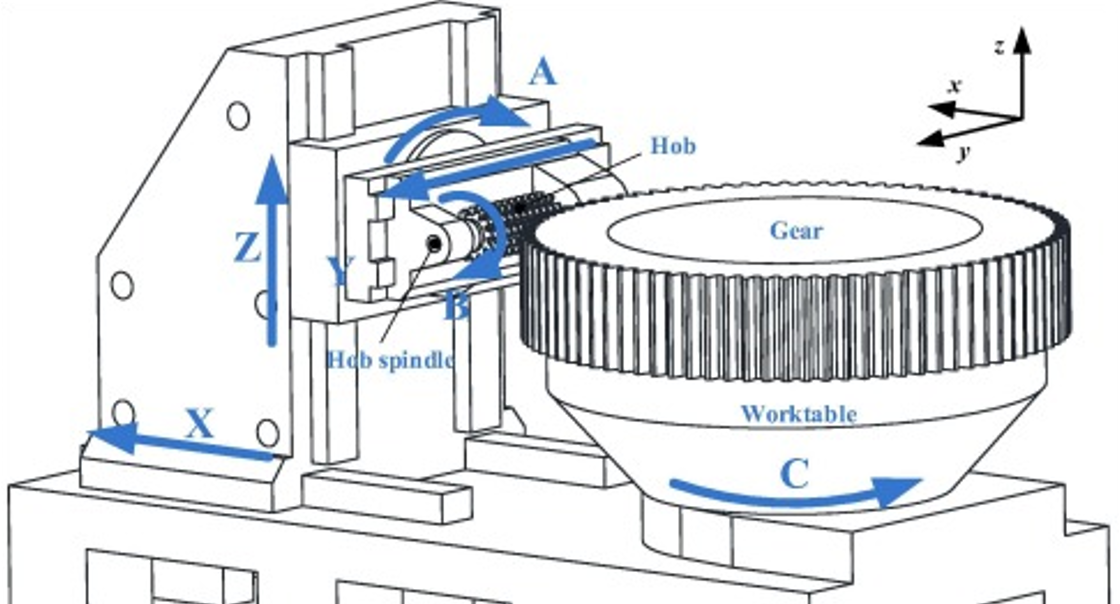

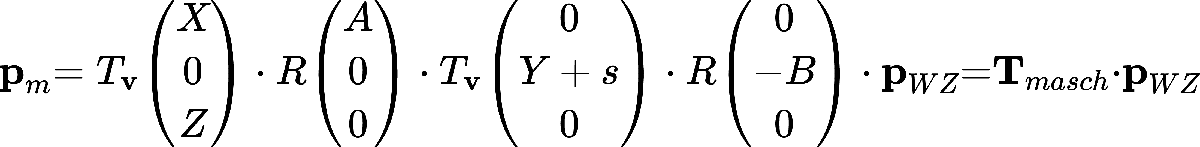

syms x y z A Y_shift B

### Koordinaten

- homogene Repräsentation, 4x4 (Matrizen) oder 4x1 (Koordinaten)

#### Werkzeugkoordinaten, kartesisch:

syms x_WZ y_WZ z_WZ
WZ_kart = dim4([x_WZ;y_WZ;z_WZ],1,'forward')

$$WZ\_kart = \left(\begin{array}{c} x_{\mathrm{WZ}}\\ y_{\mathrm{WZ}}\\ z_{\mathrm{WZ}}\\ 1 \end{array}\right)$$

#### Werkzeugkoordinaten

- Zylinderkoordinaten

- es bietet sich an, das Werkzeug in Zylinderkoordinaten anzulegen, da sich die Schneidreihen bei mehrzahnigen Werkzeugen entlang des Umfangs wiederholen

syms r_WZ phi_WZ h_WZ
WZ_zyl = dim4([r_WZ*cos(phi_WZ); r_WZ*sin(phi_WZ); h_WZ],1,'forward')

$$WZ\_zyl = \left(\begin{array}{c} r_{\mathrm{WZ}}\,\cos\left(\varphi_{\mathrm{WZ}}\right)\\ r_{\mathrm{WZ}}\,\sin\left(\varphi_{\mathrm{WZ}}\right)\\ h_{\mathrm{WZ}}\\ 1 \end{array}\right)$$

### Vorschübe

- alle Vorschübe beziehen sich auf die Drehung des Werkzeuges

#### Nomenklatur

% fZ_WZrad = 5

5mm Vorschub auf der z-Achse pro 1 Umdrehung des Werkzeugs (2*pi)

- f: Vorschub

- Z: in z-Richtung

- WZ: bezogen auf die Werkzeugdrehung

- rad: Einheit (kann man das weglassen und immer in rad rechnen)

syms fZ_WZrad fY_WZrad fX_WZrad f_WSTrad

#### Winkel C

Winkel C ist Funktion der Werkzeugrotation und Werkstückvorschub (als Vorfaktor)

- Werkstückvorschub (f_WSTrad) ist Übersetzungsverhältnis des Schneckengetriebes

- Übersetzungsverhältnis: Anzahl Schneidreihen zu Anzahl Zähne am Bauteil: $i = \frac{n_{Schneidreihen}}{n_{Zähne}}$

C = f_WSTrad * B

$$C = B\,f_{\mathrm{WSTrad}}$$

### Weitere

gesuchter z-Wert

syms z_soll

## Transformationsmatrizen

### Rotationen

#### B-Achse

Rotation um B-Achse ist um Koordinatensystem y-Achse

R_B = axang2rtm('y',-B)

$$R\_B = \left(\begin{array}{cccc} \cos\left(B\right) & 0 & -\sin\left(B\right) & 0\\ 0 & 1 & 0 & 0\\ \sin\left(B\right) & 0 & \cos\left(B\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### A-Achse

Rotation um A-Achse ist um Koordinatensystem x-Achse

R_A = axang2rtm('x',A)

$$R\_A = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(A\right) & -\sin\left(A\right) & 0\\ 0 & \sin\left(A\right) & \cos\left(A\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### C-Achse

Rotation um C-Achse ist um Koordinatensystem z-Achse

R_Cga = axang2rtm('z',C+ga)

$$R\_Cga = \left(\begin{array}{cccc} \cos\left(\mathrm{ga}+B\,f_{\mathrm{WSTrad}}\right) & -\sin\left(\mathrm{ga}+B\,f_{\mathrm{WSTrad}}\right) & 0 & 0\\ \sin\left(\mathrm{ga}+B\,f_{\mathrm{WSTrad}}\right) & \cos\left(\mathrm{ga}+B\,f_{\mathrm{WSTrad}}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Rotiertes Werkzeugkoordinatensystem

R_Wkz = floor(axang2rtm('x',pi/2))

R_Wkz =      1     0     0     0
     0     0    -1     0
     0     1     0     0
     0     0     0     1


### Translationen

#### Translation der Y-Achse mit shift

T_Ys = trvecHomTform('y',y + fY_WZrad*B + Y_shift)

$$T\_Ys = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & Y_{\mathrm{shift}}+y+B\,{\mathrm{fY}}_{\mathrm{WZrad}}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Translation der x- und z-Achse

saubere XZ-Achsen TM:

T_XZ = trvecHomTform('x',x,'z',z)

$$T\_XZ = \left(\begin{array}{cccc} 1 & 0 & 0 & x\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & z\\ 0 & 0 & 0 & 1 \end{array}\right)$$

TM für XZ-Achsen Vorschübe:

T_XZf = trvecHomTform('x',fX_WZrad*B,'z',fZ_WZrad*B)

$$T\_XZf = \left(\begin{array}{cccc} 1 & 0 & 0 & B\,{\mathrm{fX}}_{\mathrm{WZrad}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & B\,{\mathrm{fZ}}_{\mathrm{WZrad}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

TM für die Offsets des Werkstückkoordinatensystems,

geht invers ein!

T_offs = inv(trvecHomTform([a,b,c]))

$$T\_offs = \left(\begin{array}{cccc} 1 & 0 & 0 & -a\\ 0 & 1 & 0 & -b\\ 0 & 0 & 1 & -c\\ 0 & 0 & 0 & 1 \end{array}\right)$$

neue, gesamte XZ-Transformationsmatrix:

T_XZ = T_XZ * T_XZf * T_offs

$$T\_XZ = \left(\begin{array}{cccc} 1 & 0 & 0 & x-a+B\,{\mathrm{fX}}_{\mathrm{WZrad}}\\ 0 & 1 & 0 & -b\\ 0 & 0 & 1 & z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Transformationsmatrix der Maschine ohne Werkstücktransformation

Reihenfolge ergibt sich mit Linksmultiplikation durch die kinematische Kette ausgehend vom Werkzeug

damit ergibt sich TM von Werkzeug-frame in das Maschinen(bett)-frame

**in der Formel fehlt noch R_Wkz!**

TM_masch = T_XZ * R_A * T_Ys * R_B * R_Wkz

$$TM\_masch = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(B\right) & -\sin\left(B\right) & 0 & x-a+B\,{\mathrm{fX}}_{\mathrm{WZrad}}\\ -\sin\left(A\right)\,\sin\left(B\right) & -\cos\left(B\right)\,\sin\left(A\right) & -\cos\left(A\right) & \cos\left(A\right)\,\sigma_{1}-b\\ \cos\left(A\right)\,\sin\left(B\right) & \cos\left(A\right)\,\cos\left(B\right) & -\sin\left(A\right) & z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=Y_{\mathrm{shift}}+y+B\,{\mathrm{fY}}_{\mathrm{WZrad}} \end{array}$$

### Gesamt

% Gesamt = R_Cga * T_XZ * R_A * T_Ys * R_B
Gesamt = R_Cga * TM_masch

$$Gesamt = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2}\,\cos\left(B\right)+\sigma_{1}\,\sin\left(A\right)\,\sin\left(B\right) & \sigma_{1}\,\cos\left(B\right)\,\sin\left(A\right)-\sigma_{2}\,\sin\left(B\right) & \sigma_{1}\,\cos\left(A\right) & \sigma_{2}\,\sigma_{3}+\sigma_{1}\,\sigma_{4}\\ \sigma_{1}\,\cos\left(B\right)-\sigma_{2}\,\sin\left(A\right)\,\sin\left(B\right) & -\sigma_{1}\,\sin\left(B\right)-\sigma_{2}\,\cos\left(B\right)\,\sin\left(A\right) & -\sigma_{2}\,\cos\left(A\right) & \sigma_{1}\,\sigma_{3}-\sigma_{2}\,\sigma_{4}\\ \cos\left(A\right)\,\sin\left(B\right) & \cos\left(A\right)\,\cos\left(B\right) & -\sin\left(A\right) & z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\sigma_{5}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\mathrm{ga}+B\,f_{\mathrm{WSTrad}}\right)\\ \sigma_{2}=\cos\left(\mathrm{ga}+B\,f_{\mathrm{WSTrad}}\right)\\ \sigma_{3}=x-a+B\,{\mathrm{fX}}_{\mathrm{WZrad}}\\ \sigma_{4}=b-\cos\left(A\right)\,\sigma_{5}\\ \sigma_{5}=Y_{\mathrm{shift}}+y+B\,{\mathrm{fY}}_{\mathrm{WZrad}} \end{array}$$

auskommentierte TM zum Vergleich

%[ cos(ga - B*f_WSTrad)*cos(B) + sin(ga - B*f_WSTrad)*sin(A)*sin(B), -sin(ga - B*f_WSTrad)*cos(A),   sin(ga - B*f_WSTrad)*cos(B)*sin(A) - cos(ga - B*f_WSTrad)*sin(B), b*sin(ga - B*f_WSTrad) + cos(ga - B*f_WSTrad)*(X - a + B*fX_WZrad) - sin(ga - B*f_WSTrad)*cos(A)*(Y + Y_shift + B*fY_WZrad)]
%[ sin(ga - B*f_WSTrad)*cos(B) - cos(ga - B*f_WSTrad)*sin(A)*sin(B),  cos(ga - B*f_WSTrad)*cos(A), - sin(ga - B*f_WSTrad)*sin(B) - cos(ga - B*f_WSTrad)*cos(B)*sin(A), sin(ga - B*f_WSTrad)*(X - a + B*fX_WZrad) - b*cos(ga - B*f_WSTrad) + cos(ga - B*f_WSTrad)*cos(A)*(Y + Y_shift + B*fY_WZrad)]
%[                                                    cos(A)*sin(B),                       sin(A),                                                      cos(A)*cos(B),                                                                      Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad)]
%[                                                                0,                            0,                                                                  0,                                                                                                                           1]

## Anwendung der Transformationsmatrizen

### Gesamt mal Werkzeugkoordinaten

in kartesischen Koordinaten

p_WST = Gesamt * WZ_kart;
p_WST(3)

$$ans = z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\left(Y_{\mathrm{shift}}+y+B\,{\mathrm{fY}}_{\mathrm{WZrad}}\right)-z_{\mathrm{WZ}}\,\sin\left(A\right)+y_{\mathrm{WZ}}\,\cos\left(A\right)\,\cos\left(B\right)+x_{\mathrm{WZ}}\,\cos\left(A\right)\,\sin\left(B\right)$$

in zylindrischen Koordinaten

p_WST = Gesamt * WZ_zyl;
p_WST(3)

$$ans = z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\left(Y_{\mathrm{shift}}+y+B\,{\mathrm{fY}}_{\mathrm{WZrad}}\right)-h_{\mathrm{WZ}}\,\sin\left(A\right)+r_{\mathrm{WZ}}\,\cos\left(A\right)\,\cos\left(B\right)\,\sin\left(\varphi_{\mathrm{WZ}}\right)+r_{\mathrm{WZ}}\,\cos\left(A\right)\,\sin\left(B\right)\,\cos\left(\varphi_{\mathrm{WZ}}\right)$$

auskommentierter Term zum Vergleich

% Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ*sin(A) + r_WZ*cos(A)*cos(B)*sin(phi_WZ) + r_WZ*cos(A)*sin(B)*cos(phi_WZ)

### Relevanter Auszug aus der Gesamttransformationsmatrix

Gesamt(3,4)

$$ans = z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\left(Y_{\mathrm{shift}}+y+B\,{\mathrm{fY}}_{\mathrm{WZrad}}\right)$$

auskommentierter Term zum Vergleich

% Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ*sin(A) + r_WZ*cos(A)*(sin(B + phi_WZ)

## Verfahren 1

- Schritt 1: B auf einen Schätzwert festlegen, 0 pi/2 pi etc. je nach dem wo die B-Achse startet und wie die WZ-Schneide liegt

- Schritt 2: B ausrechnen: B= arcsin((z_soll - (Z - c + B*f_WZrad + sin(A)*(Y + Y_shift) + h_WZ*sin(A))))/(r_WZ*cos(A)) - phi_WZ 

- Schritt N: Schritt 2 mit neuem B durchführen bis Differenz zwischen B alt und B neu < gewählter Toleranz

- Alternativ: nach Schritt 2:  mit fzero lösen 0 == Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ*sin(A) + r_WZ*cos(A)*(sin(B + phi_WZ))-Z_soll nach B 

- z_soll ist unterschlagen

% solve( z_soll == Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ*sin(A) + r_WZ*cos(A)*(sin(B + phi_WZ)) , B )

## Verfahren 2

sinus Approximation benutzen

### Bedatung des Polynoms

k1 = 1.27323954;
k2 = 0.405284735;
syms k3

## Lösen der Gleichungen

%solve (z_soll -(Z- c + sin(A)*(Y + Y_shift) + h_WZ*sin(A)) == B*fZ_WZrad  + r_WZ*cos(A)*(sin(B + phi_WZ)) , B )

### Verwendung des approximierten Sinus

Ausgangsformel

%solve (k3 == B*fZ_WZrad  + r_WZ*cos(A)*(sin(B + phi_WZ)) , B )

Verwendung des allgemein approximierten Sinus

solve (k3 == B*fZ_WZrad  + r_WZ*cos(A)*(k1*(B + phi_WZ) - sign(B + phi_WZ)*k2*(B + phi_WZ)^2),B)

Verwendung von zwei Aufrufen, je einen für positiven und negativen Wertebereich

% solve (k3 == B*fZ_WZrad  + r_WZ*cos(A)*(k1*(B + phi_WZ) - k2*(B + phi_WZ)^2),B)
% solve (k3 == B*fZ_WZrad  + r_WZ*cos(A)*(k1*(B + phi_WZ) + k2*(B + phi_WZ)^2),B)

Verwendung der externen Funtion

solve(k3 == B*fZ_WZrad  + r_WZ*cos(A)*(sineApprox(B + phi_WZ)) , B )

 
ans =
 
Empty sym: 0-by-1
 


Maschinentransformationsmatrix mal zylindrische Werkzeugkoordinaten

TM_masch * WZ_zyl

 
ans =
 
Empty sym: 0-by-1
 


auskommentierte Lösung zum Vergleich

% [T_XZ * R_A * T_Ys * R_B] * [r_WZ*cos(phi_WZ);h_WZ;r_WZ*sin(phi_WZ);1]
%                                                                  X - a + B*fX_WZrad + r_WZ*cos(B)*cos(phi_WZ) - r_WZ*sin(B)*sin(phi_WZ)

$$ans = \begin{array}{l} \left(\begin{array}{c} x-a+B\,{\mathrm{fX}}_{\mathrm{WZrad}}+r_{\mathrm{WZ}}\,\cos\left(B\right)\,\cos\left(\varphi_{\mathrm{WZ}}\right)-r_{\mathrm{WZ}}\,\sin\left(B\right)\,\sin\left(\varphi_{\mathrm{WZ}}\right)\\ \cos\left(A\right)\,\sigma_{1}-b-h_{\mathrm{WZ}}\,\cos\left(A\right)-r_{\mathrm{WZ}}\,\cos\left(B\right)\,\sin\left(A\right)\,\sin\left(\varphi_{\mathrm{WZ}}\right)-r_{\mathrm{WZ}}\,\sin\left(A\right)\,\sin\left(B\right)\,\cos\left(\varphi_{\mathrm{WZ}}\right)\\ z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\sigma_{1}-h_{\mathrm{WZ}}\,\sin\left(A\right)+r_{\mathrm{WZ}}\,\cos\left(A\right)\,\cos\left(B\right)\,\sin\left(\varphi_{\mathrm{WZ}}\right)+r_{\mathrm{WZ}}\,\cos\left(A\right)\,\sin\left(B\right)\,\cos\left(\varphi_{\mathrm{WZ}}\right)\\ 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=Y_{\mathrm{shift}}+y+B\,{\mathrm{fY}}_{\mathrm{WZrad}} \end{array}$$

%                   cos(A)*(Y + Y_shift + B*fY_WZrad) - b + h_WZ*cos(A) - r_WZ*cos(B)*sin(A)*sin(phi_WZ) - r_WZ*sin(A)*sin(B)*cos(phi_WZ)
%  Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ*sin(A) + r_WZ*cos(A)*cos(B)*sin(phi_WZ) + r_WZ*cos(A)*sin(B)*cos(phi_WZ)

Lösung von ?

syms B_1
solve(z - c + B_1*fZ_WZrad + sin(A)*(y + Y_shift + B_1*fY_WZrad) + h_WZ*sin(A) + cos(A)*r_WZ.*sin(B-phi_WZ)==z_soll, B)

$$ans = \left(\begin{array}{c} \varphi_{\mathrm{WZ}}-\mathrm{asin}\left(\frac{z-c-z_{\mathrm{soll}}+B_{1}\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\left(Y_{\mathrm{shift}}+y+B_{1}\,{\mathrm{fY}}_{\mathrm{WZrad}}\right)+h_{\mathrm{WZ}}\,\sin\left(A\right)}{r_{\mathrm{WZ}}\,\cos\left(A\right)}\right)\\ \varphi_{\mathrm{WZ}}+\pi +\mathrm{asin}\left(\frac{z-c-z_{\mathrm{soll}}+B_{1}\,{\mathrm{fZ}}_{\mathrm{WZrad}}+\sin\left(A\right)\,\left(Y_{\mathrm{shift}}+y+B_{1}\,{\mathrm{fY}}_{\mathrm{WZrad}}\right)+h_{\mathrm{WZ}}\,\sin\left(A\right)}{r_{\mathrm{WZ}}\,\cos\left(A\right)}\right) \end{array}\right)$$

%      phi_WZ - asin((Z - c - z_soll + B_1*fZ_WZrad + sin(A)*(Y + Y_shift + B_1*fY_WZrad) + h_WZ*sin(A))/(r_WZ*cos(A)))
% phi_WZ + pi + asin((Z - c - z_soll + B_1*fZ_WZrad + sin(A)*(Y + Y_shift + B_1*fY_WZrad) + h_WZ*sin(A))/(r_WZ*cos(A)))
